# Collision avoidance simulink model

First, clear workspace and add folder with functions to path

clear
addpath("Funz");
model = "Collision_avoidance_mdl"

Choose variables for defining the problem. Both r (reference/ goal state) and x0 (initial state) are in North-East-Up coordinate frames, each row defines the state vector for a drone with states being XYZ and their derivatives.

option = "custom";
if option ~="custom"
    addpath("Scenarios");
    load(option);
else
N =30 ;%number of steps to look ahead
delta = 0.4; %collision avoidance separation
max_acc = 1; %max drone acceleration
endTime = 10; %simulation run time
MPC_period = 1; %seconds between each trajectory update

T = 0.1; %discretisation time step

r = [
     1.0,1.4,0.0, 0,0,0;
     0.6,0.4,0.0, 0,0,0;
     0.0,0.9,0.0, 0,0,0;
     0.0,0.0,1.0, 0,0,0;
     0.0,0.0,0.0, 0,0,0;
     ];

x0 = [
      0.0,0.5,0.0, 0,0,0;
      0.2,0.9,0.0, 0,0,0;
      1.0,0.3,0.0, 0,0,0;
      0.0,0.0,0.0, 0,0,0;
      0.0,0.0,1.0, 0,0,0;
      ];

M = size(x0,1); % Number of agents (derived from number of rows of x0)

graph_form{1} = ones(M) - eye(M); %connectivity graph
% graph_form{1} = [0 1 0 0; 1 0 0 0; 0 0 0 1; 0 0 1 0]; %define connection graphs
% graph_form{2} = [0 0 1 0; 0 0 0 1; 1 0 0 0; 0 1 0 0];
% graph_form{3} = [0 0 0 1; 0 0 1 0; 0 1 0 0; 1 0 0 0];

graph_update_step = 1; %how many MPC calls before connection graph is updated
end

Set up structures & buses for the model using values specified


if size(graph_form,2) == 1
    graph_form{2} = graph_form{1};
end


for i = 1:size(graph_form,2)
    graph(:,:,graph_update_step*(i-1)+1:i*graph_update_step) = graph_form{i};
end

A = [1 0 0 T 0 0;
    0 1 0 0 T 0;
    0 0 1 0 0 T;
    0 0 0 1 0 0;
    0 0 0 0 1 0;
    0 0 0 0 0 1];

B = [0 0 0;
    0 0 0;
    0 0 0;
    T 0 0;
    0 T 0;
    0 0 T];



%set up model structure
model.A = A;
model.B = B;
model.umax = max_acc;
model.umin = -max_acc;

nx = size(model.A,1); %state vector dimension
nu = size(model.B,2); %number of inputs
Nd = 3; %number of dimensions

%Objective matrices setup (note that we ignore velocity in the
%optimisation)
Q = eye(Nd)*10; 
Objective.Q = blkdiag(Q,zeros(nx-Nd));
Objective.R = eye(nu)*13;
Objective.N = N;

Acc_from_pos = eye((N+1)*Nd) + ...
               [zeros((N)*Nd,Nd) -2*eye(N*Nd); zeros(Nd,(N+1)*Nd)] + ...
               [zeros((N-1)*Nd,2*Nd) eye((N-1)*Nd); zeros(2*Nd,(N+1)*Nd)];
Acc_from_pos = Acc_from_pos/T^2;
Bus_setup; %sets up buses for model

## Run Simulation

w=warning('off','all');
tic
simout = sim(model,'StopTime', string(endTime));
sim_time = toc

sim_time = 165.7208

## View results

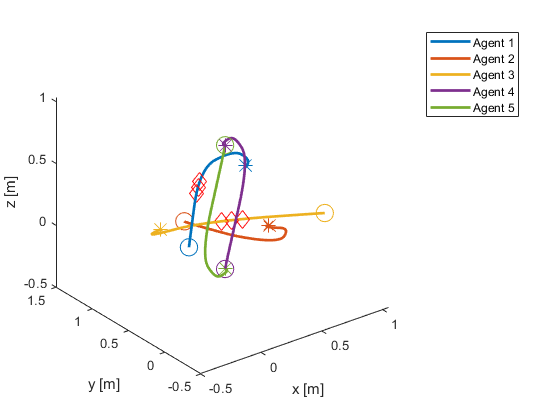

Minimum separation: 3.747382e-01 


x = reshape(simout.yout{1}.Values.Data(:,:,:),M,[])';
visualise_drones_3d(r,x,T,nx,delta);